# **Project Two Template**

## MAT-350: Applied Linear Algebra

## *Student Name: Justin Paul Guida*

## *Date: 10/16/2025*

## **Problem 1**

**Use the svd() function** in MATLAB to compute $A_{1}$, the **rank-1 approximation of** $A$**.** Clearly state what $A_{1}$ is, rounded to 4 decimal places. Also, **compute** the root-mean square error (RMSE) between $A$ and $A_{1}$. Solution:

% 3 x 3 Matrix A
A = [1 2 3;
     3 3 4;
     5 6 7]

A =      1     2     3
     3     3     4
     5     6     7


[U,S,V] = svd(A)

U =    -0.2904    0.9504   -0.1114
   -0.4644   -0.2418   -0.8520
   -0.8367   -0.1957    0.5115


S =    12.5318         0         0
         0    0.9122         0
         0         0    0.3499


V =    -0.4682   -0.8261   -0.3136
   -0.5581    0.0012    0.8298
   -0.6851    0.5635   -0.4616


% finding the rank-1 approximation of A
A1 = U(:,1:1) * S(1:1,1:1) * V(:,1:1)'

A1 =     1.7039    2.0313    2.4935
    2.7243    3.2477    3.9867
    4.9087    5.8517    7.1832


A1 = round(A1,4)  % round A1 values to 4 decimals

A1 =     1.7039    2.0313    2.4935
    2.7243    3.2477    3.9867
    4.9087    5.8517    7.1832


RankA1 = rank(A1) % check the rank

RankA1 = 3

% getting RMSE between A and A1
rmse_1 = sqrt(mean((A(:)-A1(:)).^2))

rmse_1 = 0.3256

## **Problem 2**

**Use the svd() function** in MATLAB to compute $A_{2}$, the **rank-2 approximation of** $A$. Clearly state what $A_{2}$ is, rounded to 4 decimal places. Also, **compute** the root-mean square error (RMSE) between $A$ and $A_{2}$. Which approximation is better, $A_{1}$ or $A_{2}$? Explain. Solution:

% Computing rank approximation, by adding the first two singular components
A2 = U(:,1)*S(1,1)*V(:,1)' + U(:,2)*S(2,2)*V(:,2)'

A2 =     0.9878    2.0324    2.9820
    2.9065    3.2474    3.8624
    5.0561    5.8515    7.0826


% Showing rank of A2
RankA2 = rank(A2)

RankA2 = 2

% getting RMSE between A and A2
rmse_2 = sqrt(mean((A(:)-A2(:)).^2))

rmse_2 = 0.1166

**Explain:**

**RMSE:** accounts for how different my approximation is from the original matrix. It measures the average error between A1 and A2. A smaller RMSE means the approximation is closer to the real matrix and fits it better.

## **Problem 3**

For the $3 \times 3$ matrix $A$, the singular value decomposition is $A=USV'$ where $U=[\mathbf{u}_{1} \text{ } \mathbf{u}_{2} \text{ } \mathbf{u}_{3}]$. Use MATLAB to **compute** the dot product $d_{1}=dot(\mathbf{u}_{1},\mathbf{u}_{2})$.

Also, use MATLAB to **compute** the cross product $\mathbf{c} =cross(\mathbf{u}_{1},\mathbf{u}_{2})$ and dot product $d_{2} = dot(\mathbf{c},\mathbf{u}_{3})$. Clearly state the values for each of these computations. Do these values make sense? **Explain**. Solution: $

% Extracting three column vectors from U
U1 = U(:,1), U2 = U(:,2), U3 = U(:,3)

U1 =    -0.2904
   -0.4644
   -0.8367


U2 =     0.9504
   -0.2418
   -0.1957


U3 =    -0.1114
   -0.8520
    0.5115


% compute the cross product c = cross(u1,u1); compute the dot product d2 = dot(c, u3)
c = cross(U1, U2), d2 = dot(c, U3)

c =    -0.1114
   -0.8520
    0.5115


d2 = 1.0000

**Explain:**

The dot product d2 = dot(c, U3) is 1.0000, meaning C and U3 point the same way and both have a length of 1. This shows that U1, U2, and U3 are orthogonal unit vectors. That just means they’re all perpendicular to each other and each one has a magnitude of 1. Together they make a right-handed orthonormal basis.

## **Problem 4**

Using the matrix $U=[\mathbf{u}_{1} \text{ } \mathbf{u}_{2} \text{ } \mathbf{u}_{3}]$, d*etermine whether or not the columns of* $U$ **span** $\mathbb{R}^{3}$. **Explain your approach.** Solution:

% Matrix u = [u1, u2 u3]
U = [U1, U2, U3]

U =    -0.2904    0.9504   -0.1114
   -0.4644   -0.2418   -0.8520
   -0.8367   -0.1957    0.5115



% double check and test the Rank
r = rank(U)

r = 3

spans = (r ==3) % check span is = R^3; spans = logical should be 1.

spans = logical
   1


% Use RREF to show RREF View
RREF_U = rref(U)

RREF_U =      1     0     0
     0     1     0
     0     0     1


**Explain:**

rank(U) = 3, so they span R^3

Additionally, you can see in echelon form that the matrix reduces to the identity. This means each column is independent, and together they cover the whole 3-D space.

## **Problem 5**

Use the MATLAB imshow() function to load and display the image $A$ stored in the image.mat file, available in the Project Two Supported Materials area in Brightspace. For the loaded image, **derive the value of** $k$ that will result in a compression ratio of $CR \approx 2$. For this value of $k$, **construct the rank-_k_ approximation of the image**. Solution:

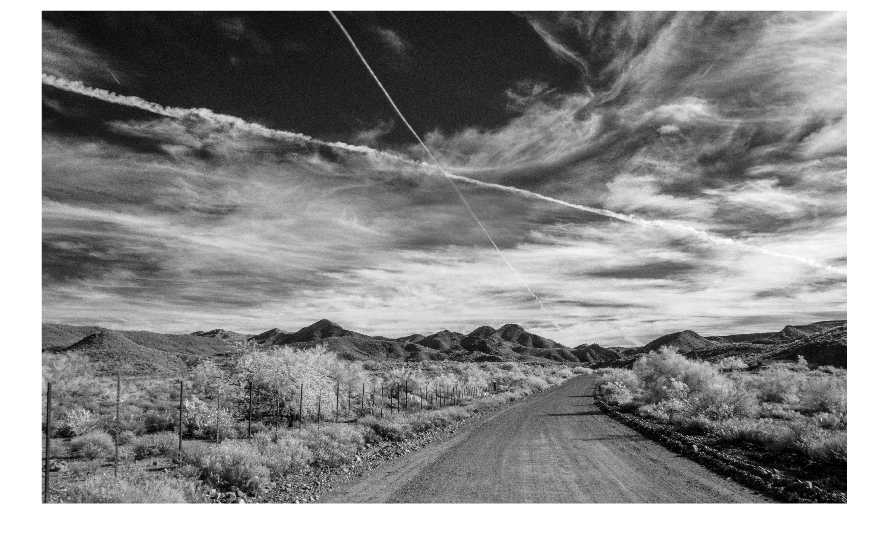

% use imshow() to load and display image A
load("/Users/jguida941/Downloads/MAT 350 Project Two MATLAB Image.mat")
imshow(A)

% get the size of the image
[m,n] = size(A)

m = 2583

n = 4220

% 1st I set the target compression ratio (CR) and solve for k
% The formula is CR = (m*n) / (k*(m + n + 1))
% It is rearranged to find k that gives the CR
CR = 2;
k = round((m*n)/(CR*(m+n+1)));
disp(['Calculated k for CR≈', num2str(CR), ' is ', num2str(k)])

Calculated k for CR≈2 is 801


% make the rank-k version of the image
[U,S,V] = svd(double(A),'econ')

U =     0.0106    0.0360    0.0006   -0.0032    0.0032   -0.0041    0.0066   -0.0022    0.0199   -0.0059    0.0138   -0.0154   -0.0124    0.0102   -0.0118    0.0036   -0.0034    0.0066   -0.0026    0.0069   -0.0064    0.0004   -0.0112    0.0049    0.0202   -0.0061    0.0107    0.0005    0.0045   -0.0149    0.0130   -0.0065    0.0079   -0.0008    0.0031   -0.0212    0.0101   -0.0000    0.0199   -0.0029    0.0033   -0.0077    0.0066   -0.0047    0.0143   -0.0025    0.0156   -0.0202    0.0147   -0.0111
    0.0105    0.0361    0.0006   -0.0030    0.0035   -0.0049    0.0062   -0.0020    0.0204   -0.0058    0.0139   -0.0152   -0.0122    0.0092   -0.0112    0.0030   -0.0026    0.0074   -0.0018    0.0079   -0.0065    0.0003   -0.0109    0.0046    0.0191   -0.0068    0.0109    0.0018    0.0046   -0.0145    0.0117   -0.0065    0.0084   -0.0024    0.0014   -0.0215    0.0104   -0.0006    0.0188   -0.0016    0.0002   -0.0099    0.0067   -0.0059    0.0139   -0.0035    0.0148   -0.0191    0.0160   -0

S = 1.0e+05 *

    4.0600         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.8702         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

V =     0.0130   -0.0044    0.0358   -0.0028    0.0085   -0.0177   -0.0128    0.0163   -0.0298   -0.0045    0.0006   -0.0122    0.0143    0.0020    0.0278    0.0168    0.0247   -0.0296   -0.0061    0.0127    0.0002   -0.0341   -0.0001   -0.0281    0.0342   -0.0119    0.0180   -0.0288   -0.0170   -0.0066   -0.0389   -0.0040    0.0194    0.0004    0.0153   -0.0092   -0.0073    0.0082   -0.0234    0.0223   -0.0039    0.0161   -0.0252    0.0082   -0.0099   -0.0221   -0.0117    0.0063   -0.0117   -0.0623
    0.0130   -0.0045    0.0357   -0.0024    0.0079   -0.0184   -0.0134    0.0162   -0.0309   -0.0038    0.0012   -0.0120    0.0149    0.0027    0.0256    0.0158    0.0245   -0.0296   -0.0086    0.0136    0.0003   -0.0356    0.0005   -0.0279    0.0357   -0.0122    0.0190   -0.0286   -0.0170   -0.0083   -0.0401   -0.0037    0.0168    0.0027    0.0141   -0.0088   -0.0065    0.0056   -0.0205    0.0219   -0.0031    0.0151   -0.0232    0.0073   -0.0127   -0.0161   -0.0120    0.0054   -0.0119   -0

A_compressed = U(:,1:k)*S(1:k,1:k)*V(:,1:k)'

A_compressed =    26.4896   27.2541   30.5810   28.9530   23.3828   25.7705   35.1037   29.3968   32.9167   35.7277   29.6657   25.5423   31.8075   27.1097   27.9802   33.7315   31.1819   30.8813   27.8016   20.0656   19.7837   30.7982   31.4131   27.6530   26.5889   30.2995   31.2249   25.9122   32.7232   31.2294   23.0459   19.7503   33.1269   31.7624   37.3639   32.4922   27.4063   28.1858   23.7386   21.9973   22.4652   26.4795   27.0546   19.7551   22.2834   24.8839   22.4499   23.8428   28.9766   23.6715
   32.6831   34.0733   28.4258   30.5682   27.6882   28.4547   35.6629   31.2002   29.6536   27.3993   22.4987   27.5956   39.5807   33.7341   33.5815   34.0165   32.8017   33.0654   28.2675   17.3682   21.3168   29.9663   27.9044   25.2467   24.2990   26.7841   35.5123   33.3932   29.3797   25.7284   22.1742   18.5305   27.7917   32.7620   35.3463   29.3516   29.6410   27.8408   22.1847   24.3495   24.1099   24.3442   24.2253   20.3470   22.3034   26.3346   20.6531   15.8503   2

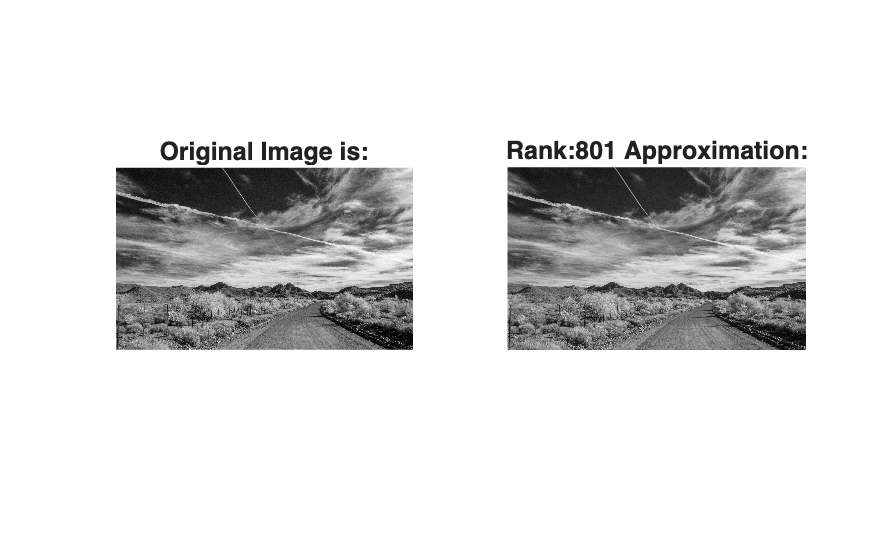

% show both images side by side to double check
figure
subplot(1,2,1), imshow(A,[]), title('Original Image is:')
subplot(1,2,2), imshow(A_compressed,[]), title(['Rank:', num2str(k), ' Approximation:'])

% final check 

% same image size, and rank should equal k
size(A), size(A_compressed), rank(A_compressed), k 

ans =         2583        4220


ans =         2583        4220


ans = 801

k = 801

**Explain:**

SVD was used to rebuild the image using the top k singular values that give a compression ratio of around CR = 2. This allows the resulting image to keep most of its detail while also reducing data size. The rank-k version proves the image can be rebuilt with far fewer values without losing key structure.

## **Problem 6**

**Display the image and compute** the root mean square error (RMSE) between the approximation and the original image. Make sure to include a copy of the approximate image in your report. Solution:

close all
% Displayed with imshow(A, []) using double precision
% Converting to uint8 is unnecessary in modern MATLAB and slightly alters
% the RMSE due to quantization. The display works correctly without conversion
imshow(A_compressed, [])
RMSEk = norm(double(A)-A_compressed,'fro')/sqrt(m*n)

RMSEk = 3.1539

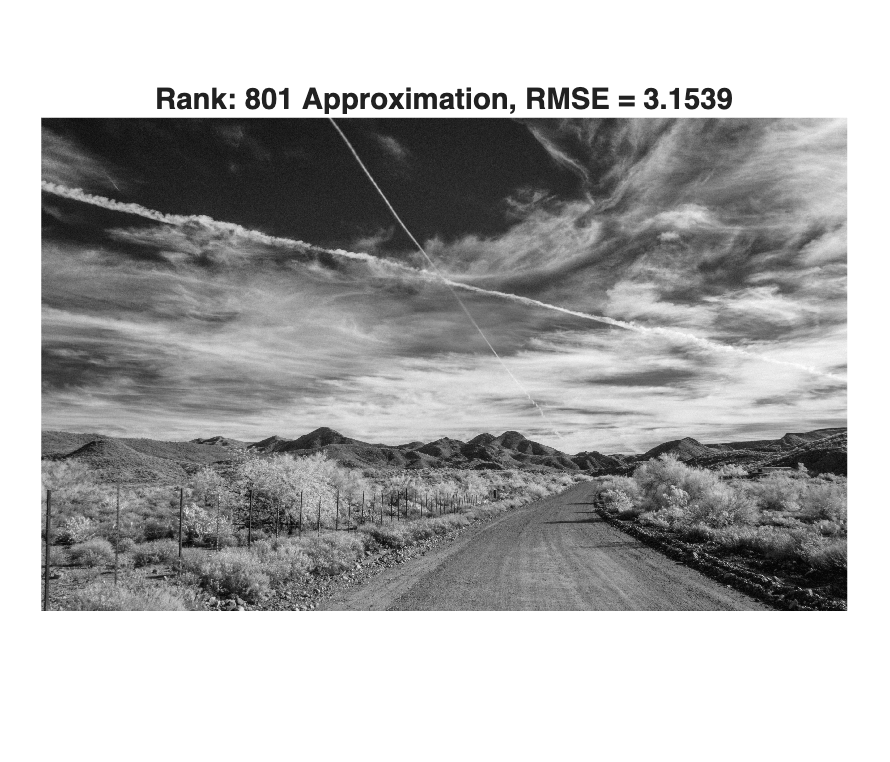

title(sprintf('Rank: %d Approximation, RMSE = %.4f', k, RMSEk))
set(gcf,'Position',[100 100 700 600])  % fit window

## **Problem 7**

**Repeat** Problems 5 and 6 for $CR \approx 10$, $CR \approx 25$, and $CR \approx 75$. **Explain** what trends you observe in the image approximation as $CR$ increases and provide your recommendation for the best $CR$ based on your observations. Make sure to include a copy of the approximate images in your report. Solution:

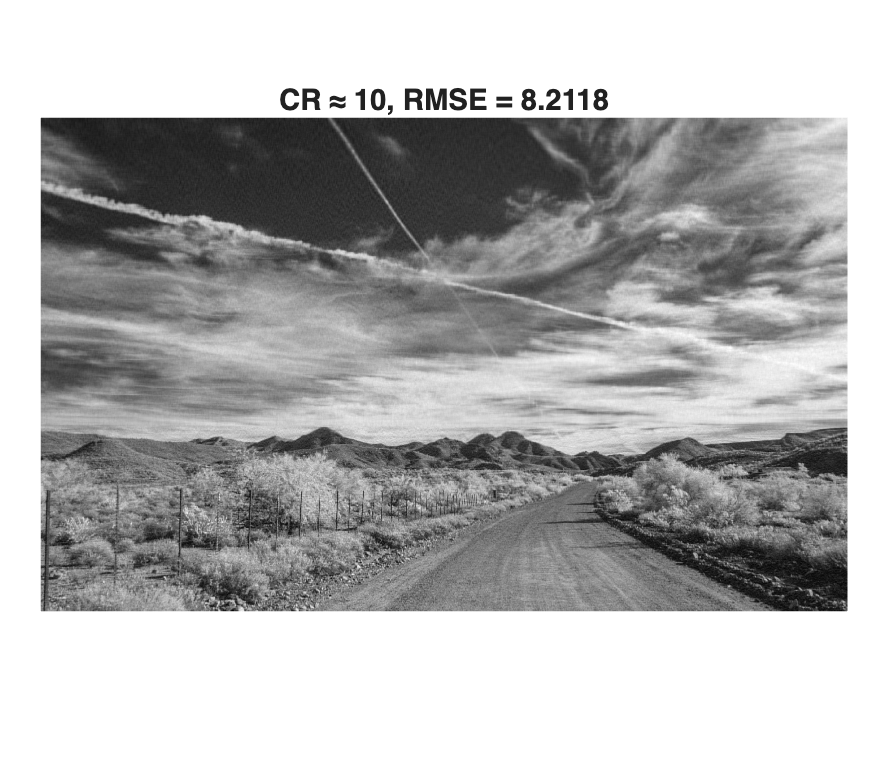

% repeat the problems 5, 6 
% with CR = 10, 25, and 75

% precompute once
[m,n] = size(A);
[U,S,V] = svd(double(A),'econ');

% CR = 10
CR = 10;                         % set target compression ratio to 10
k = round((m*n)/(CR*(m+n+1)));   % solve for k using CR formula

% build rank-k approximation using the first k singular values
A10 = U(:,1:k)*S(1:k,1:k)*V(:,1:k)';

% calculate RMSE to measure the differance in this image compared to the original
RMSE10 = norm(double(A)-A10,'fro')/sqrt(m*n);

% display the new compressed image and display CR  and RMSE for the title
figure, imshow(A10,[])
title(['CR ≈ 10, RMSE = ', num2str(RMSE10)]);set(gcf,'Position',[100 100 700 600]) % fit in title % CR = 25

CR = 25; k = round((m*n)/(CR*(m+n+1)));
A25 = U(:,1:k)*S(1:k,1:k)*V(:,1:k)';
RMSE25 = norm(double(A)-A25,'fro')/sqrt(m*n);
figure, imshow(A25,[]), title(['CR ≈ 25, RMSE = ', num2str(RMSE25)]); set(gcf,'Position',[100 100 700 600]) % fit in title % CR = 25
% CR = 75
CR = 75; k = round((m*n)/(CR*(m+n+1)));
A75 = U(:,1:k)*S(1:k,1:k)*V(:,1:k)';
RMSE75 = norm(double(A)-A75,'fro')/sqrt(m*n);
figure, imshow(A75,[]), title(['CR ≈ 75, RMSE = ', num2str(RMSE75)]); set(gcf,'Position',[100 100 700 600]) % fit in title % CR = 25
% Display RMSE values for rank-1 and rank-2 approximations
disp(['RMSE for rank-1 approximation: ', num2str(rmse_1)]);, disp(['RMSE for rank-2 approximation: ', num2str(rmse_2)]);

RMSE for rank-1 approximation: 0.32565
RMSE for rank-2 approximation: 0.11664


disp('My suggestion would be CR ≈ 15:')

My suggestion would be CR ≈ 15:


CR = 15; 
k15 = round((m*n)/(CR*(m+n+1)));
A15 = U(:,1:k15)*S(1:k15,1:k15)*V(:,1:k15)';
RMSE15 = norm(double(A)-A15,'fro')/sqrt(m*n);
figure; imshow(A15,[]);
set(gcf,'Position',[100 100 700 600]);
title(['My suggestion would be: CR ≈ 15, RMSE = ', num2str(RMSE15)]);
disp(['RMSE for CR ≈ 15: ', num2str(RMSE15)]);

RMSE for CR ≈ 15: 9.9268


**Explain:**

At a low compression rate (like CR=10), the image remains sharper and more detailed but the trade off is more storage.

A medium compression rate (CR=25) reduces the file size, but the trade off is itt introduces some blurring and texture loss.

At a high rate (CR=75), the image becomes heavily blurred showing the trade-off between size and quality.

To find a better balance, I calculated CR≈15 using the same formula. This value keeps more singular components than CR=25, so edges and fine details stay clearer, while the file size is still much smaller than at CR=10.

Based on the results, CR≈15 provides the best compromise between visual quality and compression efficiency.

But if I had to choose only between CR=10, CR=25, and CR=75, I would pick CR=25. It keeps most of the image structure while still reducing the file size more effectively than CR=10.